**EE 699 Next Generation Wireless Networks - Assignment 01**

- **a. PSS Detection**

- **Specifications:**

Number of Transmitters = 1 and Number of Receivers = 2

% All possible PSS sequences :
N_zc = 63 ;
PSS_freq = [] ;
mu_zc = [25, 29, 34] ;
for i = 1:3 
    x_pss = [] ;
    for n = 0: 30
        x_pss = [x_pss exp(-1j * pi * n * (n+1) * mu_zc(i) / N_zc)] ;
    end
    for n = 31: 61
        x_pss = [x_pss exp(-1j * pi * (n+1) * (n+2) * mu_zc(i) / N_zc)] ;
    end
    PSS_freq = [PSS_freq
        x_pss] ;
end
% Time domain PSS :
PSS_time = [ifft(PSS_freq(1,:), N_fft)
  ifft(PSS_freq(1,:), N_fft)
  ifft(PSS_freq(2,:), N_fft)] ;

% Adding the cyclic prefixes :
PSS_time = [PSS_time(1, N_fft-8:N_fft) PSS_time(1,:)
    PSS_time(2, N_fft-8:N_fft) PSS_time(2,:)
    PSS_time(3, N_fft-8:N_fft) PSS_time(3,:)] ;

% Sequence generation 
% Parameters
N_fft = 128 ;
del_F = 15 * 10 ^ 3 ;
Fs = N_fft * del_F ;
num_rf = 2 ;

num_sf = num_rf * 10 ;
num_slots = num_sf * 2 ;
slot_duration = 0.5 * 10 ^ -3 ;
sf_duration = 2 * slot_duration ;
rf_duration = 10 * sf_duration ;

% DL waveform generation :
DL_BSignal = RFgenerator(num_rf) ;
circshift(DL_BSignal, 36, 1) ;
% Modulation :
[lteTxWaveform, info] = lteOFDMModulate(enb, DL_BSignal);
info

info = struct with fields:
           SamplingRate: 1920000
                   Nfft: 128
              Windowing: 4
    CyclicPrefixLengths: [10 9 9 9 9 9 9 10 9 9 9 9 9 9]


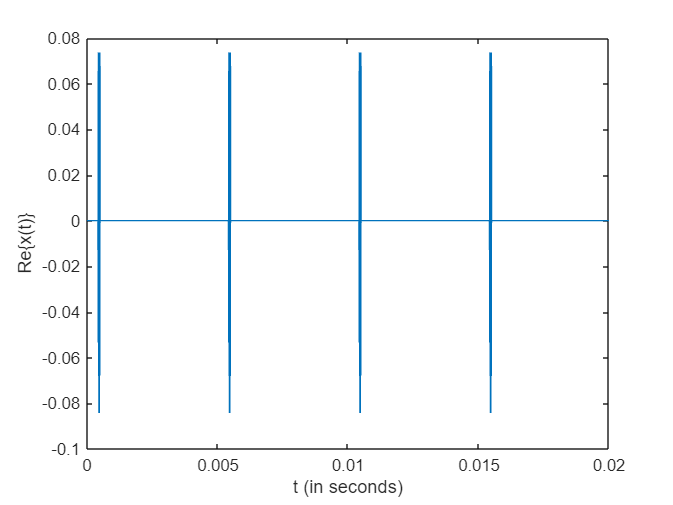

del_t = 1 / (N_fft * del_F) ; 
t_axis = 0: del_t: rf_duration * num_rf - del_t ;

plot(t_axis, real(lteTxWaveform)); 
xlabel('t (in seconds)') ;
ylabel('Re\{x(t)\}') ;

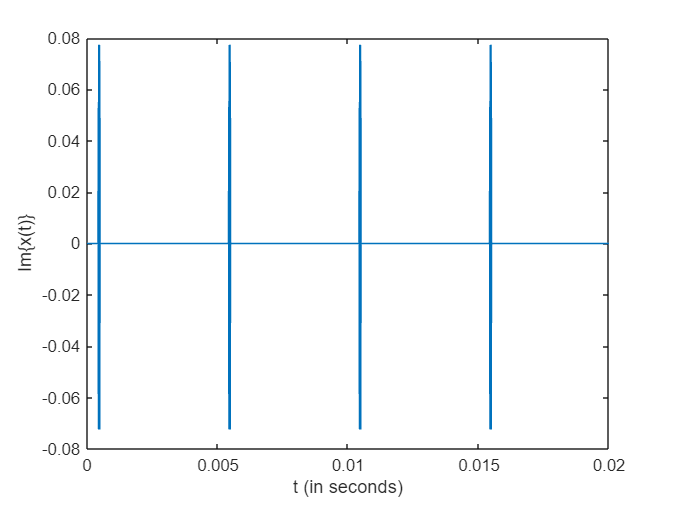

plot(t_axis, imag(lteTxWaveform)); 
xlabel('t (in seconds)') ;
ylabel('Im\{x(t)\}') ;

**Non-Coherent Detection **

i. Using Time Domain Correlation

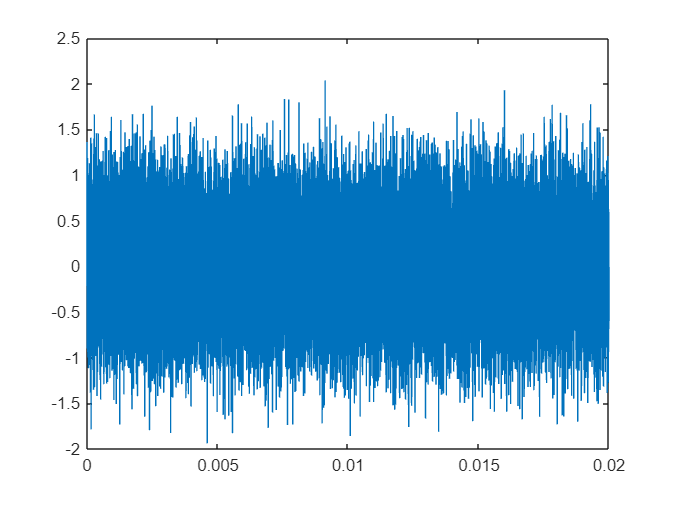

% For AWGN channel
% Adding Noise :
mu = 0 ;
sig2 = 0.5 ;
noise_samples = normrnd(mu, sig2, size(lteTxWaveform)) + 1j * normrnd(mu, sig2, size(lteTxWaveform))  ;
rx_signal = lteTxWaveform + noise_samples ; % Noisy signal 
plot(t_axis, real(rx_signal))


% Doing correlation :


% For Rayleigh channel


ii. Using Frequency Domain

% For AWGN channel 
 

% For Rayleigh channel

**Function definitions**:

function DL_signal = RFgenerator(numRF)
    % Cell Wide Parameters
    enb.NDLRB = 6 ; % Number of DL Resource Blocks
    enb.Cyclicprefix = 'Normal' ; % Type of CP (length)
    enb.NCellID = 1 ;
    enb.CellRefP = 1 ;
    enb.DuplexMode = 'FDD';
     
    radioFrame = [] ;
    for i=0:9
       enb.NSubframe = i ;    
        % PSS symbols and indices for antenna 1 and 2:
        pss_symbols = ltePSS(enb) ;
        antenna = 0 ;
        pss_indices = ltePSSIndices(enb, antenna) ;
        
        % One Sub frame formation :
        subframe = lteDLResourceGrid(enb);
        subframe(pss_indices) = pss_symbols;
        
        % One radio frame formation :
        radioFrame = [radioFrame subframe] ;
    end
    
    % N radio frames formation 
    DL_signal = [] ;
    while (numRF > 0)
        DL_signal = [DL_signal radioFrame] ;
        numRF = numRF - 1 ;
    end
end